# ENAE311H - HW05

## Problem 1

### Part A

syms M
gamma = 1.4

gamma = 1.4000


p0p = (1 + (gamma - 1)/2 * M^2)^(gamma / (gamma - 1))

$$p0p = {\left(\frac{M^{2}}{5}+1\right)}^{7/2}$$

t0t = 1 + (gamma - 1)/2 * M^2

$$t0t = \frac{M^{2}}{5}+1$$

a0a = sqrt(1 + (gamma - 1)/2 * M^2)

$$a0a = \sqrt{\frac{M^{2}}{5}+1}$$

aastar = ((gamma + 1) * M)/(1 + gamma * M^2)

$$aastar = \frac{12\,M}{5\,\left(\frac{7\,M^{2}}{5}+1\right)}$$

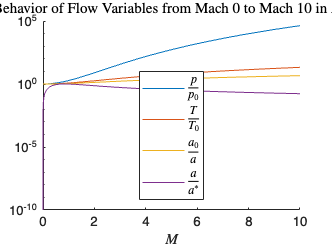


figure;
hold on;
fplot(p0p, [0 10])
fplot(t0t, [0 10])
fplot(a0a, [0 10])
fplot(aastar, [0 10])
xscale("linear")
yscale("log")
xlabel("$M$", Interpreter="latex")
ylabel("")
title("Behavior of Flow Variables from Mach 0 to Mach 10 in Air", Interpreter="latex")
legend("$\frac{p}{p_{0}}$", "$\frac{T}{T_{0}}$", "$\frac{a_{0}}{a}$", "$\frac{a}{a^{*}}$", Interpreter="latex", Location="South")
hold off;

### Part B

syms M
gamma = 1.8

gamma = 1.8000


p0p = (1 + (gamma - 1)/2 * M^2)^(gamma / (gamma - 1))

$$p0p = {\left(\frac{2\,M^{2}}{5}+1\right)}^{9/4}$$

t0t = 1 + (gamma - 1)/2 * M^2

$$t0t = \frac{2\,M^{2}}{5}+1$$

a0a = sqrt(1 + (gamma - 1)/2 * M^2)

$$a0a = \sqrt{\frac{2\,M^{2}}{5}+1}$$

aastar = ((gamma + 1) * M)/(1 + gamma * M^2)

$$aastar = \frac{14\,M}{5\,\left(\frac{9\,M^{2}}{5}+1\right)}$$

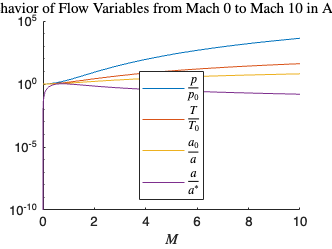


figure;
hold on;
fplot(p0p, [0 10])
fplot(t0t, [0 10])
fplot(a0a, [0 10])
fplot(aastar, [0 10])
xscale("linear")
yscale("log")
xlabel("$M$", Interpreter="latex")
ylabel("")
title("Behavior of Flow Variables from Mach 0 to Mach 10 in Argon", Interpreter="latex")
legend("$\frac{p}{p_{0}}$", "$\frac{T}{T_{0}}$", "$\frac{a_{0}}{a}$", "$\frac{a}{a^{*}}$", Interpreter="latex", Location="South")
hold off;

### Part C

syms M
gamma = 1.28

gamma = 1.2800


p0p = (1 + (gamma - 1)/2 * M^2)^(gamma / (gamma - 1))

$$p0p = {\left(\frac{7\,M^{2}}{50}+1\right)}^{32/7}$$

t0t = 1 + (gamma - 1)/2 * M^2

$$t0t = \frac{7\,M^{2}}{50}+1$$

a0a = sqrt(1 + (gamma - 1)/2 * M^2)

$$a0a = \sqrt{\frac{7\,M^{2}}{50}+1}$$

aastar = ((gamma + 1) * M)/(1 + gamma * M^2)

$$aastar = \frac{57\,M}{25\,\left(\frac{32\,M^{2}}{25}+1\right)}$$

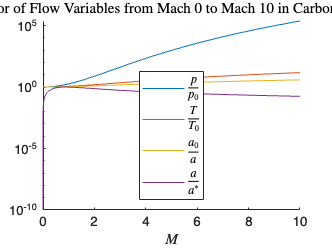


figure;
hold on;
fplot(p0p, [0 10])
fplot(t0t, [0 10])
fplot(a0a, [0 10])
fplot(aastar, [0 10])
xscale("linear")
yscale("log")
xlabel("$M$", Interpreter="latex")
ylabel("")
title("Behavior of Flow Variables from Mach 0 to Mach 10 in Carbon Dioxide", Interpreter="latex")
legend("$\frac{p}{p_{0}}$", "$\frac{T}{T_{0}}$", "$\frac{a_{0}}{a}$", "$\frac{a}{a^{*}}$", Interpreter="latex", Location="South")
hold off;

## Problem 5

### Part A

syms Ms gamma

M2prime = simplify(((1+2*gamma/(gamma+1)*(Ms^2-1))*(2+(gamma-1)*Ms^2)/((gamma+1)*Ms^2))^(-1/2)*Ms-((2+(gamma-1)*Ms^2)/(2*gamma*Ms^2-(gamma-1)))^(1/2), IgnoreAnalyticConstraints=true)

$$M2prime = \frac{2\,{\mathrm{Ms}}^{2}-2}{\sqrt{2\,\gamma \,{\mathrm{Ms}}^{2}-\gamma +1}\,\sqrt{{\mathrm{Ms}}^{2}\,\gamma -{\mathrm{Ms}}^{2}+2}}$$

simplify(limit(M2prime, Ms, inf), IgnoreAnalyticConstraints=true)

$$ans = \frac{\sqrt{2}}{\sqrt{\gamma }\,\sqrt{\gamma -1}}$$

### Part B

M2prime5 = vpa(subs(subs(M2prime, Ms, 5), gamma, 1.4))

$$M2prime5 = 1.6609095970747993765694125559143$$

ps = 101e3

ps = 101000

Ts = 300

Ts = 300


p02 = (1+2*gamma/(gamma+1)*(Ms^2-1))*((gamma+1)^2*Ms^2/(4*gamma*Ms^2-2*(gamma-1)))^(gamma/(gamma-1))*ps

$$p02 = 101000\,\left(\frac{2\,\gamma \,\left({\mathrm{Ms}}^{2}-1\right)}{\gamma +1}+1\right)\,{\left(\frac{{\mathrm{Ms}}^{2}\,{\left(\gamma +1\right)}^{2}}{4\,\gamma \,{\mathrm{Ms}}^{2}-2\,\gamma +2}\right)}^{\frac{\gamma }{\gamma -1}}$$

T02 = (1+(gamma-1)/2*Ms^2)*Ts

$$T02 = 300\,{\mathrm{Ms}}^{2}\,\left(\frac{\gamma }{2}-\frac{1}{2}\right)+300$$


p025 = vpa(subs(subs(p02, Ms, 5), gamma, 1.4))

$$p025 = 3298000.905542122321559439803414$$

T025 = vpa(subs(subs(T02, Ms, 5), gamma, 1.4))

$$T025 = 1800.0$$

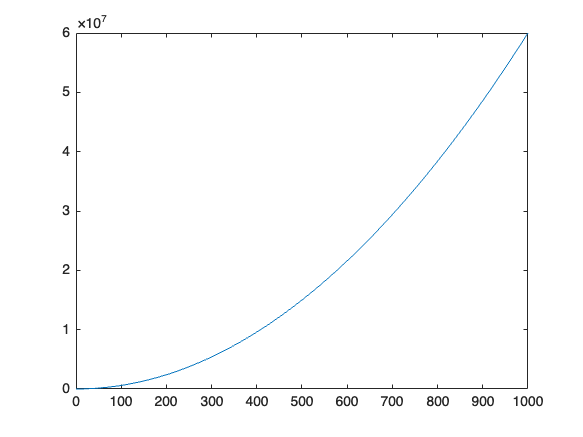


fplot(subs(T02, gamma, 1.4), [0 1000])